Create figure, axes and plot data into it:

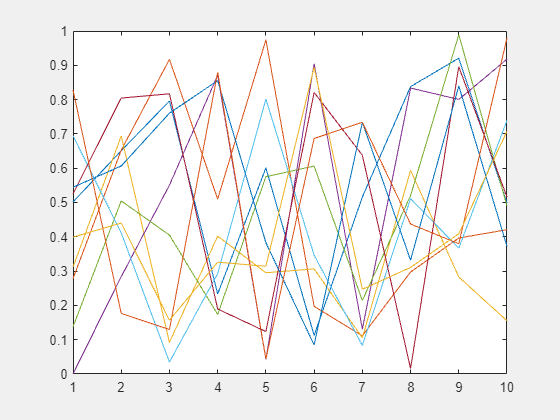

fig=uifigure('AutoResizeChildren','off');
set(fig,'SizeChangedFcn',@panel_size_changer);
ax=axes(fig);
plot(ax,rand(10));

Get the plotted objects from figure:

objs=findobj(ax);

Create a panel in the figure:

panel_=uipanel(fig,'Title','Legend','AutoResizeChildren','off','SizeChangedFcn',@legend_size_changer);
% panel_.
panel_.BackgroundColor=[0.5 0.5 0.5 0.1];
panel_.Units="pixels";
sz=fig.Position;
panel_.Position=[sz(3)-80 1 70 sz(4)-10];
panel_.Units="pixels";
panel_size=panel_.Position;
total=length(objs)-1;
width_step=panel_size(3)-1;
height_step=panel_size(4)/total;

Create Button for every object in the panel:

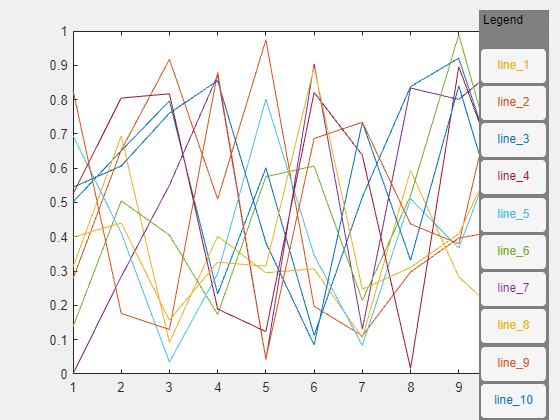


for ind=2:length(objs)
    obj=objs(ind);
    obj.Tag="line_"+string(ind-1);
    h_start=(ind-2)*height_step+1;
    h_end=height_step-1;
    pos=[1 h_start panel_size(3)-3 h_end];
    btn=uibutton('Parent',panel_,'Text',obj.Tag,'Position',pos);
    set(btn,"ButtonPushedFcn",{@legend_handler,obj});

    btn.FontColor=obj.Color;
    % btn.Position=[1 h_start width_step,h_end];
end

Callbacks Here:

function legend_handler(src,event,h)
    if h.Visible
        h.Visible='off';
    else
        h.Visible='on';
    end
end
function legend_size_changer(src,event)
    objs=findobj(src);
    panel_size=src.Position;
    total=length(objs);
    width_step=panel_size(3)-3;
    height_step=panel_size(4)/total;
    for ind=2:length(objs)
        obj=objs(ind);
        h_start=(ind-2)*height_step+1;
        h_end=height_step-1;
        pos=[1 h_start width_step,h_end];
        obj.Position=pos;
    end
end
function panel_size_changer(src,event)
 obj=findobj(src,'Type','uipanel');
 sz=src.Position;
 obj.Position=[sz(3)-80 1 70 sz(4)-10];
end
